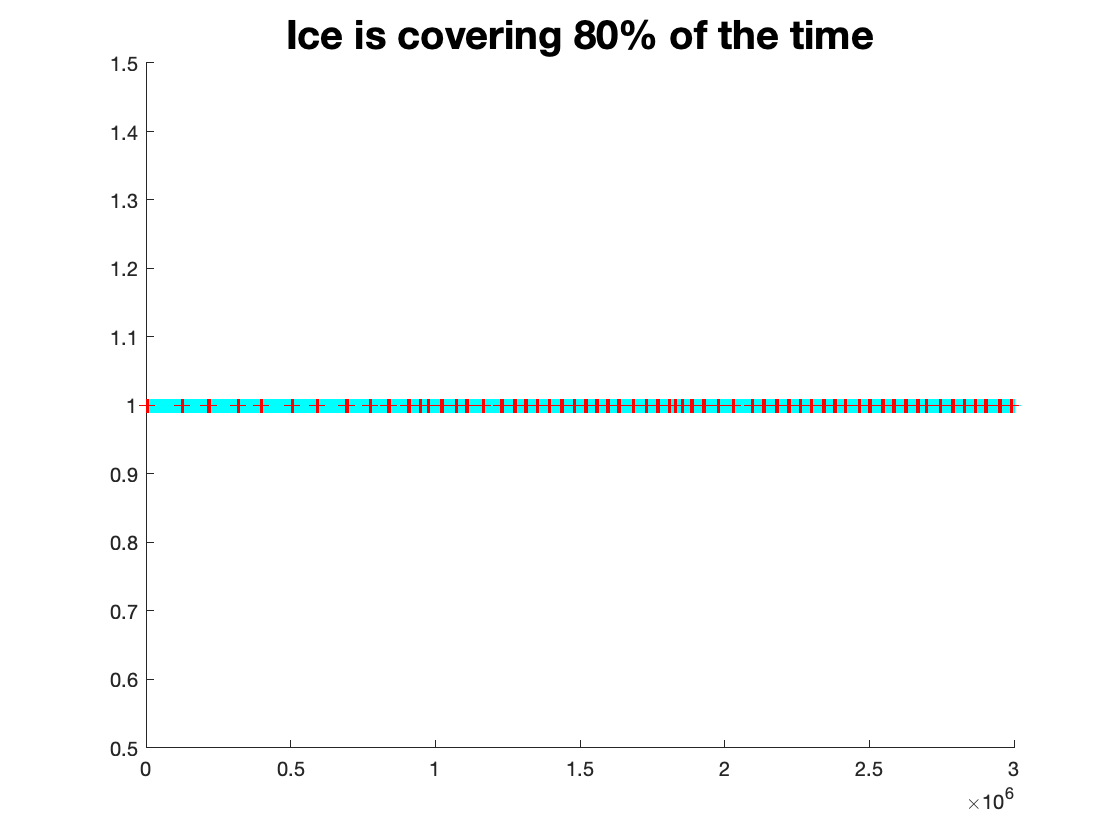

% This scripte calculates 10Be and 26Al concenrations in a bedrock profile at sea level
% and high latitude for various erosion rates (see 'erosion' variable) and using 
% the frequent-interglacial scenario, with exposure during every Pleistocene
% interglacial in the LR04 stack, but assuming production by muons through 50 meters of 
% ice during glacial times (as shown in Extended Data Figure 11 
% and 10 in LeBlanc et al.,unpublished).

% run the following scenarios prior to plotting: 
% % scenario no. = start; nhg; IG length; glacial erosion rate; background erosion rate 
% 15 = 8 Ma; 3.0 Ma; 10kyr; [1, 10, 100]; 20

% acronyms used in code notes:
% G = glacial
% IG = interglacial
% NHG = northern hemisphere glaciation
% MPT = mid-pleistocene transition
% ka = thousand years before present

% exposure scenario 1 but simulate nuclide production by muons through 50 m of ice when covered 

%%%%%%%%%%% INITIAL INPUTS %%%%%%%%%%%% ADJUST BEFORE RUNNING %%%%%%%%%%%
a = 15; % scenario no.
start = 8e6; % start of model, years
stop = 0; % end of model, years
nhg = 3.0e6; % onset of northern hemisphere glaciation, years
mpt = 1.0e6; % mid-pleistocene transition, years
interglacials = xlsread('inputs.xlsx','interglacials')*1000; % import prescribed interglacial intervals, based on Lisiecki and Raymo (2005) - Ages of MIS boundaries
interglacials = round(interglacials(1:61,3),-3);
time = flip((stop:1000:start)'); % years @ 1000 year timesteps
timestep = time(1)-time(2); % length of timestep, 1000 years
erosion = [1 10 100]; % ice erosion during glacials, mm/timestep(kyr)
backgrounderosion = 20; % pre-NHG background erosion, in rock, mm/timestep(kyr)
length_of_interglacial = 10; % IG length, kyr
long_ep = 0; % 1 = doubles pre-MPT IG length, 0 = same pre-and post-MPT IG length

% %%%%%%%%% END OF INITIAL INPUTS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% import bedrock profile
prodpro = xlsread('inputs.xlsx','production_profiles');
depthinitial = prodpro(1:72375,1)*10; % interpolating PR increment from cm to mm
depthinitialg = prodpro(1701:end,1)*10;
depth = (depthinitial(1):1:depthinitial(end))'; % depth in mm
depthg = (depthinitialg(1):1:depthinitialg(end))'; 

% import production rate profiles for 26al and 10be
% production profile under interglacial conditions
pr_be10 = prodpro(1:72375,8);
pr_be10 = interp1(depthinitial,pr_be10,depth); % interpolates between depth intervals 
pr_al26 = prodpro(1:72375,9);
pr_al26 = interp1(depthinitial,pr_al26,depth); % interpolates between depth intervals 

% production profile under glacial conditions 
pr_be10g = prodpro(1701:end,8);
pr_be10g = interp1(depthinitialg,pr_be10g,depthg); % interpolates between depth intervals 
pr_al26g = prodpro(1701:end,9);
pr_al26g = interp1(depthinitialg,pr_al26g,depthg); % interpolates between depth intervals 

% generate exposure history
initial_exposure = zeros(length(find(time>=nhg & time <= start)),1);
interglacial_zeros = zeros(length_of_interglacial,1);
time_nhgstart = time(find(time == nhg):end-1);
icecover = ones(length(time_nhgstart),1);

if length_of_interglacial == 1 % runs for IG = 1-kyr
    for index = 1:length(interglacials)
        if interglacials(index,1) <= mpt
            ig_input = find(time_nhgstart == interglacials(index,1)); % find time of IG
            icecover([ig_input:(ig_input+length_of_interglacial-1)]) = interglacial_zeros; % insert ice
        else
            if long_ep == 1
                ig_input = find(time_nhgstart == interglacials(index,1));% find time of IG
                length_of_interglacial = length_of_interglacial * 2; % multiply IG x2
                interglacial_zeros3 = repmat(interglacial_zeros,2,1); % make exposure zeros x2
                icecover([ig_input:(ig_input+length_of_interglacial-1)]) = interglacial_zeros3; % insert exposure
            else
                ig_input = find(time_nhgstart == interglacials(index,1)); % find time of IG
                icecover([ig_input:(ig_input+length_of_interglacial-1)]) = interglacial_zeros; % insert exposure
            end
        end
    end
else % runs for IG > 1-kyr
    for index = 1:length(interglacials)
        if interglacials(index,1) <= mpt
            ig_input = find(time_nhgstart == interglacials(index,1));
            check = (ig_input-(length_of_interglacial/2)):(ig_input+(length_of_interglacial/2)-1);
            check(check<=0)= 1;
            icecover(check) = interglacial_zeros;
        else
            if long_ep == 1 % doubles pre-MPT IG length
                length_of_interglacial = length_of_interglacial * 2; % multiply IG x2
                interglacial_zeros3 = repmat(interglacial_zeros,2,1); % make exposure zeros x2
                ig_input = find(time_nhgstart == interglacials(index,1));
                check = (ig_input-(length_of_interglacial/2)):(ig_input+(length_of_interglacial/2)-1);
                check(check<=0)= 1;
                icecover(check) = interglacial_zeros; % insert exposure into exposure history
            else % same pre-and post-MPT IG length
                ig_input = find(time_nhgstart == interglacials(index,1));
                check = (ig_input-(length_of_interglacial/2)):(ig_input+(length_of_interglacial/2)-1);
                check(check<=0)= 1;
                icecover(check) = interglacial_zeros; % insert exposure into exposure history
            end
        end
    end
end

% generate bedrock profile for 10be and 26al

onset = find(time == nhg); % find the onset of northern hemisphere glaciation
conditions = [initial_exposure; icecover]; % add initial pre-glaciation exposure
conditions(1:onset) = 2;

conc_be10_1 = zeros(length(depth),length(erosion)); % make vector for 10be concentrations
conc_al26_1 = zeros(length(depth),length(erosion)); % make vector for 26al concentrations

for ind1 = 1:length(erosion)
    concbe = conc_be10_1(:,ind1);
    concal = conc_al26_1(:,ind1);
    for ind2 = 1:length(time)
        surfbe10(ind2,ind1) = concbe(1,1);
        surfal26(ind2,ind1) = concal(1,1);
        if conditions(ind2) == 1 % glacial, ice sheet ON, production OFF, erosion ON
            erodeddepth = erosion(1,ind1);
            % 10be
            concbe = concbe.*exp(-timestep.*(log(2)/1.4e6)) + pr_be10g.*timestep; % decay only, production
            irdbe10(ind2,ind1) = mean(concbe(1:erodeddepth));
            topbe10 = concbe(erodeddepth+1:end,1);
            bottombe10 = zeros(erodeddepth,1);
            concbe = [topbe10; bottombe10];
            % 26al
            concal = concal.*exp(-timestep.*(log(2)/0.7e6)) + pr_al26g.*timestep;
            irdal26(ind2,ind1) = mean(concal(1:erodeddepth));
            topal26 = concal(erodeddepth+1:end,1);
            bottomal26 = zeros(erodeddepth,1);
            concal = [topal26; bottomal26];
        elseif conditions(ind2) == 2 % pre-glacial, no ice cover or IRD, only background erosion, exposure, and decay
            % 10be
            irdbe10(ind2,ind1) = 0;
            concbe = concbe.*exp(-timestep.*(log(2)/1.4e6)) + pr_be10.*timestep; % ice cover should all be 0 (no ice)
            topbe10 = concbe(backgrounderosion+1:end,1);
            bottombe10 = zeros(backgrounderosion,1);
            concbe = [topbe10; bottombe10];
            % 26al
            irdal26(ind2,ind1) = 0;
            backgrounderosion = 20;
            concal = concal.*exp(-timestep.*(log(2)/0.7e6)) + pr_al26.*timestep; % ice cover should all be 0 (no ice)
            topal26 = concal(backgrounderosion+1:end,1);
            bottomal26 = zeros(backgrounderosion,1);
            concal = [topal26; bottomal26];
        else % interglacial, ice sheet OFF, production & decay ON
            % 10be
            irdbe10(ind2,ind1) = 0;
            concbe = concbe.*exp(-timestep.*(log(2)/1.4e6)) + pr_be10.*timestep*(1-conditions(ind2));
            % 26al
            irdal26(ind2,ind1) = 0;
            concal = concal.*exp(-timestep.*(log(2)/0.7e6)) + pr_al26.*timestep*(1-conditions(ind2));
        end
    end
end

% save outputs

i1 = find(time == nhg);
i2 = find(time == 0);

% saved 10be & 26 al results from erosion rate 1
savedbe_surf_er1(:,a) = surfbe10([i1:i2],1);
savedbe_ird_er1(:,a) = irdbe10([i1:i2],1);
savedal_surf_er1(:,a) = surfal26([i1:i2],1);
savedal_ird_er1(:,a) = irdal26([i1:i2],1);

% saved 10be & 26 al results from erosion rate 2

savedbe_surf_er2(:,a) = surfbe10([i1:i2],2);
savedbe_ird_er2(:,a) = irdbe10([i1:i2],2);
savedal_surf_er2(:,a) = surfal26([i1:i2],2);
savedal_ird_er2(:,a) = irdal26([i1:i2],2);

% saved 10be & 26 al results from erosion rate 3

savedbe_surf_er3(:,a) = surfbe10([i1:i2],3);
savedbe_ird_er3(:,a) = irdbe10([i1:i2],3);
savedal_surf_er3(:,a) = surfal26([i1:i2],3);
savedal_ird_er3(:,a) = irdal26([i1:i2],3);

% plots ice cover history
inverseplot = icecover + ones(length(icecover),1);
percent_icecovered = (sum(icecover)/length([icecover])*100);

figure
scatter(time_nhgstart,icecover(1:length(time_nhgstart)),'c+')
hold on
scatter(time_nhgstart,inverseplot(1:length(time_nhgstart)),'r+')
title(['Ice is covering ' num2str(round(percent_icecovered)) '% of the time'], 'FontSize',20);
ylim([0.5 1.5])
xlim([0 3e6])
hold off